clear;
close all;

[files, path] = uigetfile( ...
    '\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Analysis\Calcium\*.mat', ...
    'Select files','MultiSelect','on');

if ischar(files)
    files = {files};
end

allData = struct();

count = 0

count = 0

for i = 1:numel(files)
    fname = fullfile(path, files{i});

    % Find the threshSum-like variable name
    info = whos('-file', fname);
    matchIdx = find(contains({info.name}, 'AUC', 'IgnoreCase', true), 1);

    if isempty(matchIdx)
        warning('No variable containing "AUC" in %s', files{i});
        continue
    end

    varname = info(matchIdx).name;
    S = load(fname, varname);
    data = S.(varname);      % struct from this file

    fList = fieldnames(data);

    for f = 1:numel(fList)
        oldFld = fList{f};
        count = count +1;

        % ---- POSTFIX: add file index at the end ----
        newFld = sprintf('%s_%02d', oldFld, count);

        % If name still collides (very rare), append "_dup"
        while isfield(allData, newFld)
            newFld = [newFld '_dup'];
        end

        allData.(newFld) = data.(oldFld);
    end
end

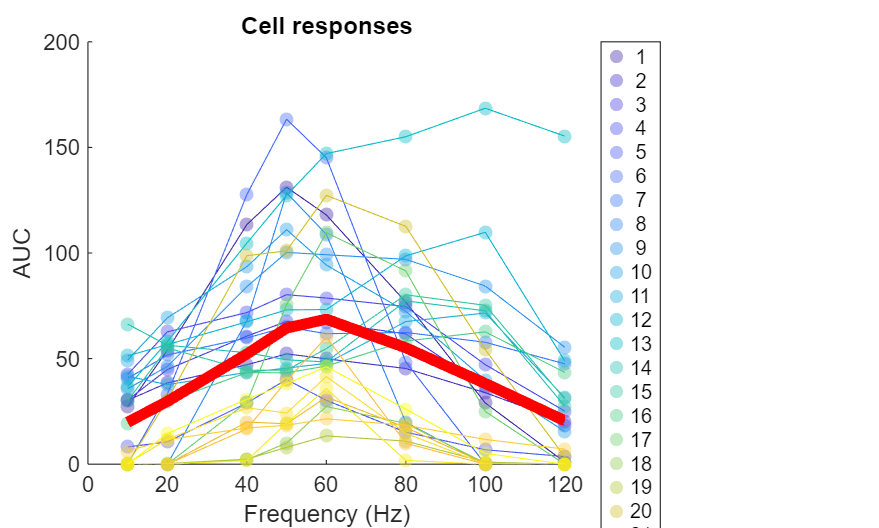

freqs = [10 20 40 50 60 80 100 120];

fi1 = figure; hold on;
fields = fieldnames(allData);

colors = parula(numel(fields));
neuronIndex = zeros(length(fields),1);
data_norm_Struct = struct();
All_data_freq = zeros(length(freqs), length(fields));

m = length(fields);
n = length(freqs); 
Matrix = zeros(m,n);

for i = 1:length(fields)
    data = allData.(fields{i}).MeanAreaCurve;
    data_max = max(data);
    data_norm = data/data_max;
    data_norm_Struct.(fields{i}) = data_norm;
    All_data_freq(:,i) = data;
    Matrix(i, :) = data;
    tokens = regexp(fields{i}, '(\d+)$', 'tokens');
    neuronIndex(i) = str2double(tokens{1}{1});
    if length(data) ~= length(freqs)
        errordlg('Wrong input data structure!')
    end
    c = colors(i, :);
        scatter(freqs, data, 40, c, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8, ...
        'DisplayName', fields{i}(end));
    plot(freqs, data, '-', 'Color', c,'HandleVisibility', 'off'); 
end
set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'Position', [0.10 0.12 0.65 0.80]); 

Mean_data_freq = mean(All_data_freq,2);
plot(freqs, Mean_data_freq, '-', 'Color', 'r','LineWidth',5, 'DisplayName','All mean');

xlabel('Frequency (Hz)');
ylabel('AUC');
title('Cell responses');
legend(num2str(neuronIndex), 'Location', 'northeastoutside');
hold off;

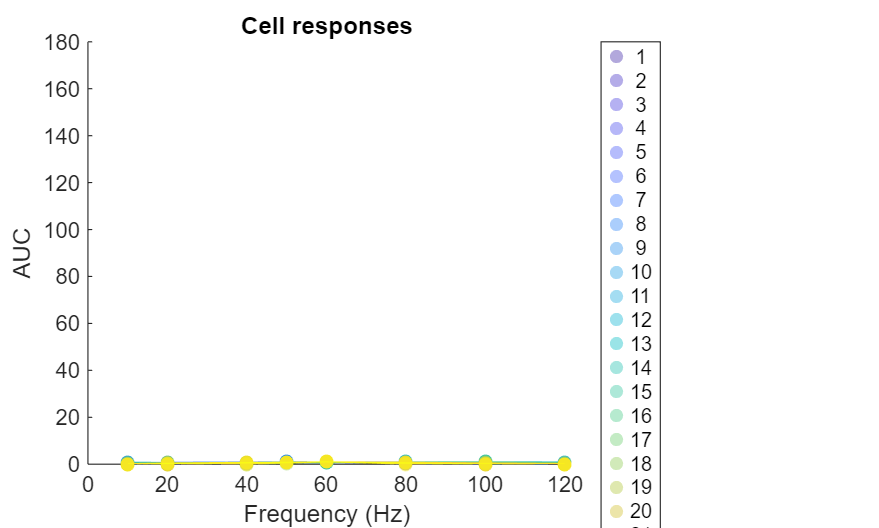


%Normalized by cell
fi2 = figure; hold on;
for i = 1:length(fields)
    data_norm = data_norm_Struct.(fields{i});
    c = colors(i, :);
        scatter(freqs, data_norm, 40, c, 'filled', ...
        'MarkerFaceAlpha', 0.4, 'MarkerEdgeAlpha', 0.8, ...
        'DisplayName', fields{i}(end));
    plot(freqs, data_norm, '-', 'Color', c,'HandleVisibility', 'off'); 
end
set(gcf, 'Position', [100 100 1000 600]); 
set(gca, 'Position', [0.10 0.12 0.65 0.80]); 

xlabel('Frequency (Hz)');
ylabel('AUC');
ylim([0 180]);
title('Cell responses');
legend(num2str(neuronIndex), 'Location', 'northeastoutside');
hold off;

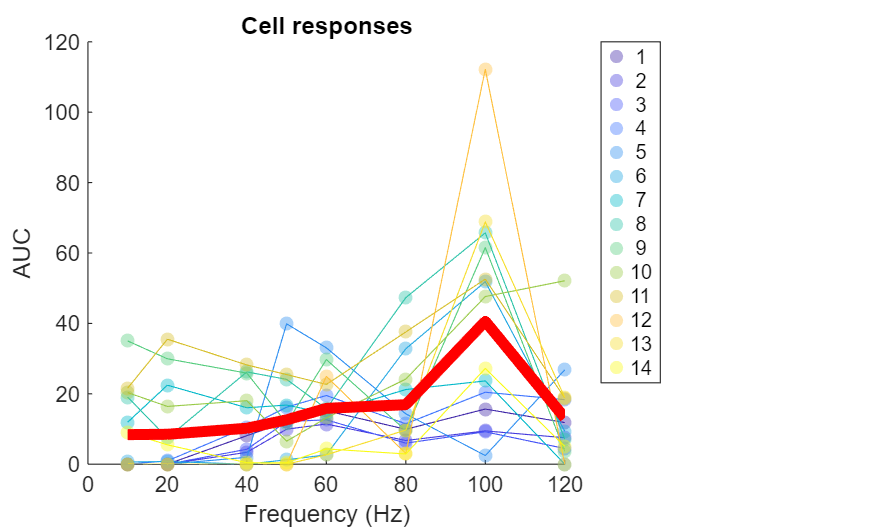

figureName_allneuron = strcat(path,"\CombinedFrequencytuning_AUC.pdf");
exportgraphics(fi1, figureName_allneuron,"Resolution",300);

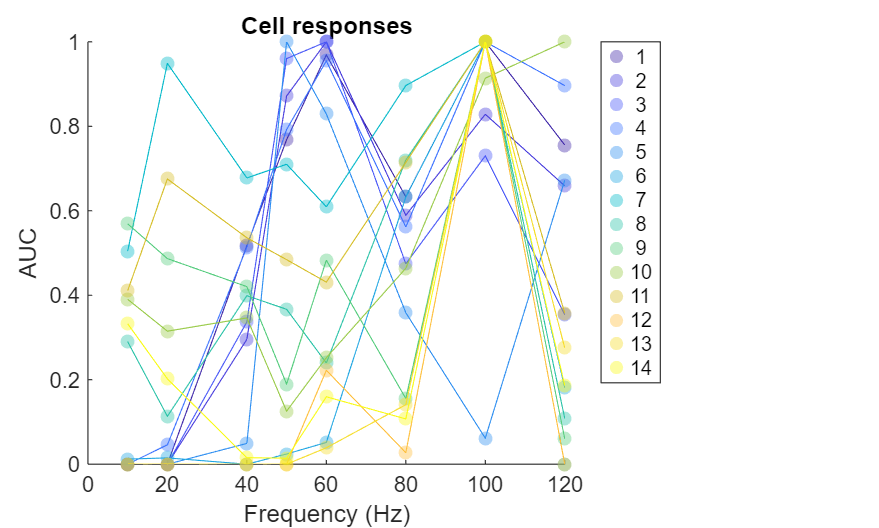

figureName_allneuron_norm = strcat(path,"\CombinedFrequencytuning_normalizedAUC.pdf");
exportgraphics(fi2, figureName_allneuron_norm,"Resolution",300);

[~, folderName] = fileparts(fileparts(path));
MatrixName_allneuron = strcat(path,folderName,"_CombinedFrequencytuning_AUC.mat");
save(MatrixName_allneuron, 'Matrix');